一、将广义被控对象近似成一阶惯性环节加延迟：

clear;
% =========请输入：广义被控对象===========
num=1;  % 零点
den=conv([2,1],[1,1]); % 极点
t=0.15;  % 系统自带的延迟
% =========请输入：仿真时间==============
time=100;
% ======================================
G=tf(num,den);   
disp("近似后的系统参数");

近似后的系统参数


[K,T,tao]=approximate(G,t)  % 计算法求参数（书P47）

K = 1.0000

T = 2.4000

tao = 0.9500

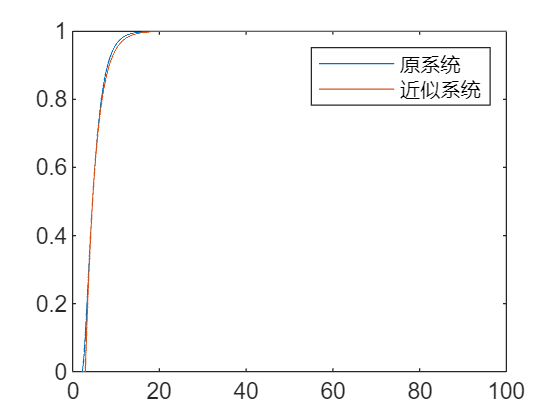


% 使用simulink比较原系统和近似后的系统
load_system('compare.slx');
sim('compare',[2 100]);   % 仿真时间
data=ans.out;
figure;
plot(data(:,1),data(:,2));hold on;
plot(data(:,1),data(:,3));hold off;
legend("原系统","近似系统");

二、使用工程整定方法求PID参数：

1、动态特性参数法——Z-N、C-C、性能指标法

计算参数Kp、Ki、Kd

% Z-N法
disp("动态特性参数法——Z-N法");

动态特性参数法——Z-N法



% P
Kc=T/(tao*K);

Kp_P=Kc;
Ki_P=0;
Kd_P=0;

% PI
Kc=T/(tao*K*1.1);
Ti=3.3*tao;

Kp_PI=Kc;
Ki_PI=Kc/Ti;
Kd_PI=0;

% PID
Kc=T/(tao*K*0.85);
Ti=2*tao;
Td=0.5*tao;

Kp_PID=Kc;
Ki_PID=Kc/Ti;
Kd_PID=Kc*Td;

% 使用simulink进行仿真
load_system('PID.slx');
sim('PID',[0 time]);   % 仿真时间
ZN=ans.out;



% C-C法
disp("动态特性参数法——C-C法");

动态特性参数法——C-C法



% P
Kc=((T/tao)+0.333)/K;

Kp_P=Kc;
Ki_P=0;
Kd_P=0;

% PI
Kc=(0.9*(T/tao)+0.082)/K;
tp = tao/T;
Ti=T*(3.33*tp+0.3*tp^2)/(1+2.2*tp);

Kp_PI=Kc;
Ki_PI=Kc/Ti;
Kd_PI=0;

% PID
Kc=(1.35*(T/tao)+0.27)/K;
tp = tao/T;
Ti=T*(2.5*tp+0.5*tp^2)/(1+0.6*tp);
Td=T*0.37*tp/(1+0.2*tp);

Kp_PID=Kc;
Ki_PID=Kc/Ti;
Kd_PID=Kc*Td;

% 使用simulink进行仿真
load_system('PID.slx');
sim('PID',[0 time]);   % 仿真时间
CC=ans.out;



% 性能指标法（Z-N） 
disp("动态特性参数法——性能指标法（Z-N）");

动态特性参数法——性能指标法（Z-N）



% P
A=1;B=1;
Kc=A*(tao/T)^(-B)/K;

Kp_P=Kc;
Ki_P=0;
Kd_P=0;

% PI
A=0.9;B=1;C=3.333;D=1;
Kc=A*(tao/T)^(-B)/K;
Ti=C*(tao/T)^(D)*T;

Kp_PI=Kc;
Ki_PI=Kc/Ti;
Kd_PI=0;

% PID
A=1.2;B=1;C=2;D=1;E=0.5;F=1;
Kc=A*(tao/T)^(-B)/K;
Ti=C*(tao/T)^(D)*T;
Td=E*(tao/T)^(F)*T;

Kp_PID=Kc;
Ki_PID=Kc/Ti;
Kd_PID=Kc*Td;

% 使用simulink进行仿真
load_system('PID.slx');
sim('PID',[0 time]);   % 仿真时间
index_ZN=ans.out;

2、稳定边界法

disp("稳定边界法");

稳定边界法


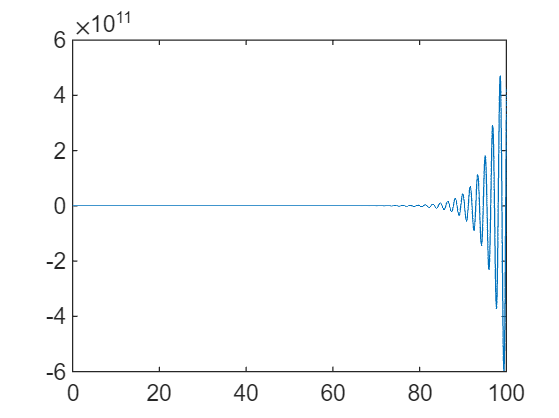


% =========请修改：Kp_P，使输出震荡===============
%           然后根据图像得出Ts，修改Ts 
% ==============================================
Kp_P=30;
Ki_P=0;Kd_P=0;Kp_PI=0;Ki_PI=0;Kd_PI=0;Kp_PID=0;Ki_PID=0;Kd_PID=0;
% 运行simulink
load_system('PID.slx');
sim('PID',[0 100]);   % 仿真时间
% 画图查看衰减率
figure;
plot(ans.out(:,1),ans.out(:,2));hold off;


Kc=Kp_P;
delte_cr=1/Kc;
Tcr=2.73

Tcr = 2.7300


% P
Kc=1/(2*delte_cr);

Kp_P=Kc;
Ki_P=0;
Kd_P=0;

% PI
Kc=1/(2.2*delte_cr);
Ti=0.85*Tcr;

Kp_PI=Kc;
Ki_PI=Kc/Ti;
Kd_PI=0;

% PID
Kc=1/(1.67*delte_cr);
Ti=0.5*Tcr;
Td=0.125*Tcr;

Kp_PID=Kc;
Ki_PID=Kc/Ti;
Kd_PID=Kc*Td;

% 使用simulink进行仿真
load_system('PID.slx');
sim('PID',[0 time]);   % 仿真时间
stable=ans.out;

3、衰减曲线法（衰减率0.75）

disp("衰减曲线法");

衰减曲线法


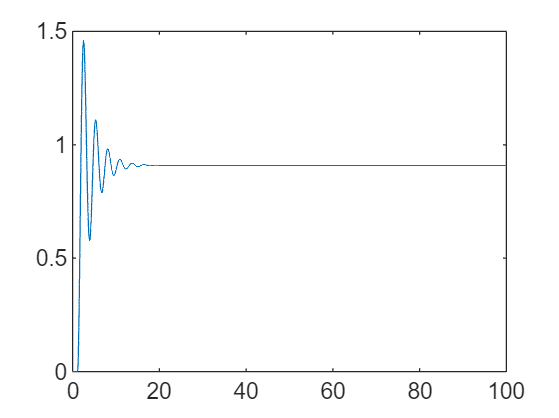


% =========请修改：Kp_P，使衰减率达0.75===========
%           然后根据图像得出Ts，修改Ts 
% ==============================================
Kp_P=10;
Ki_P=0;Kd_P=0;Kp_PI=0;Ki_PI=0;Kd_PI=0;Kp_PID=0;Ki_PID=0;Kd_PID=0;
% 运行simulink
load_system('PID.slx');
sim('PID',[0 100]);   % 仿真时间
% 画图查看衰减率
figure;
plot(ans.out(:,1),ans.out(:,2));hold off;


Kc=Kp_P;
Ts=4.6;

% P
Kc=1/(2*delte_cr);

Kp_P=Kc;
Ki_P=0;
Kd_P=0;

% PI
Ti=0.5*Ts;

Kp_PI=Kc/1.2;
Ki_PI=Kc/Ti;
Kd_PI=0;

% PID
Ti=0.3*Ts;
Td=0.1*Ts;

Kp_PID=Kc/0.8;
Ki_PID=Kc/Ti;
Kd_PID=Kc*Td;

% 使用simulink进行仿真
load_system('PID.slx');
sim('PID',[0 time]);   % 仿真时间
dicrease=ans.out;

4、经验整定法

disp("经验整定法");

经验整定法


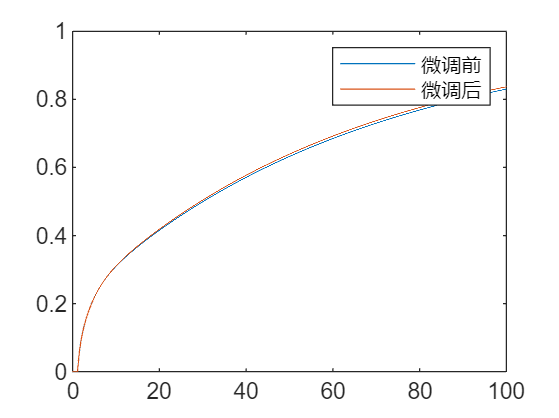

% ====== 根据三、中图像选取最佳参数，并填入 =======
%       Z-N法获得的PID较好，以此为基础微调
% ==============================================
Kp_PID = 0.3318;
Ki_PID = 0.0195;
Kd_PID = 1.4103;

Kp_P=0;Ki_P=0;Kd_P=0;Kp_PI=0;Ki_PI=0;Kd_PI=0;
load_system('PID.slx');
sim('PID',[0 time]);   % 仿真时间
experience1=ans.out;

% ============ 进行微调(主要减小超调) ============
Kp_PID = 0.33;
Ki_PID = 0.02;
Kd_PID = 1.41;

load_system('PID.slx');
sim('PID',[0 time]);   % 仿真时间
experience2=ans.out;
figure;
plot(experience1(:,1),experience1(:,4));hold on;
plot(experience2(:,1),experience2(:,4));hold on;
legend('微调前','微调后')
hold off;

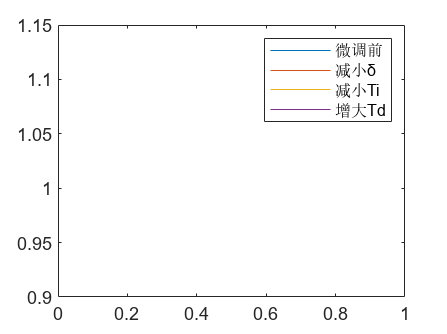


% 在设定值扰动下整定参数对输出的影响
% ================== 进行微调 ==================
%               (增大Kp/减小δ)
%               (增大Ki/减小Ti)
%               (增大Kd/增大Td)
% ==============================================
Kp_PID=Kp_PID*1.1;
load_system('PID.slx');
sim('PID',[0 time]);   % 仿真时间
experience3=ans.out;

Kp_PID=Kp_PID/1.1;
Ki_PID=Ki_PID*1.1;
load_system('PID.slx');
sim('PID',[0 time]);   % 仿真时间
experience4=ans.out;

Ki_PID=Ki_PID/1.1;
Kd_PID=Kd_PID*1.1;
load_system('PID.slx');
sim('PID',[0 time]);   % 仿真时间
experience5=ans.out;

figure;
plot(experience2(:,1),experience2(:,4));hold on;
plot(experience3(:,1),experience3(:,4));hold on;
plot(experience4(:,1),experience4(:,4));hold on;
plot(experience5(:,1),experience5(:,4));hold on;
legend('微调前','减小δ','减小Ti','增大Td');
ylim([0.9,1.15]);
hold off;

三、画图比较不同方法算出的P、PI、PID参数对应的阶跃响应曲线

纵向比较（不同方法间）

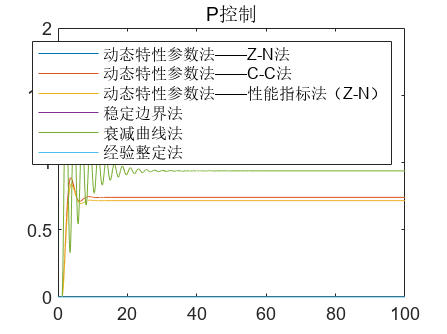

figure;
plot(ZN(:,1),ZN(:,2));hold on;
plot(CC(:,1),CC(:,2));hold on;
plot(index_ZN(:,1),index_ZN(:,2));hold on;
plot(stable(:,1),stable(:,2));hold on;
plot(dicrease(:,1),dicrease(:,2));hold on;
plot(experience2(:,1),experience2(:,2));hold on;
title("P控制");
legend('动态特性参数法——Z-N法','动态特性参数法——C-C法','动态特性参数法——性能指标法（Z-N）','稳定边界法','衰减曲线法','经验整定法');
hold off;

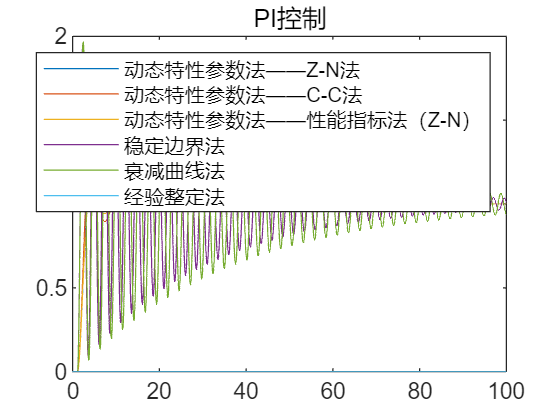


figure;
plot(ZN(:,1),ZN(:,3));hold on;
plot(CC(:,1),CC(:,3));hold on;
plot(index_ZN(:,1),index_ZN(:,3));hold on;
plot(stable(:,1),stable(:,3));hold on;
plot(dicrease(:,1),dicrease(:,3));hold on;
plot(experience2(:,1),experience2(:,3));hold on;
title("PI控制");
legend('动态特性参数法——Z-N法','动态特性参数法——C-C法','动态特性参数法——性能指标法（Z-N）','稳定边界法','衰减曲线法','经验整定法');
hold off;

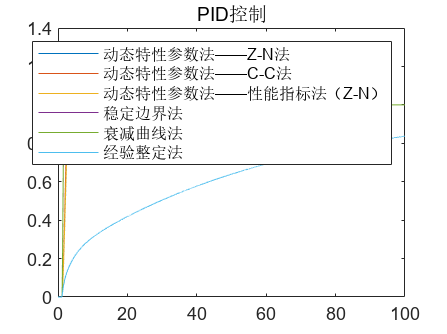


figure;
plot(ZN(:,1),ZN(:,4));hold on;
plot(CC(:,1),CC(:,4));hold on;
plot(index_ZN(:,1),index_ZN(:,4));hold on;
plot(stable(:,1),stable(:,4));hold on;
plot(dicrease(:,1),dicrease(:,4));hold on;
plot(experience2(:,1),experience2(:,4));hold on;
title("PID控制");
legend('动态特性参数法——Z-N法','动态特性参数法——C-C法','动态特性参数法——性能指标法（Z-N）','稳定边界法','衰减曲线法','经验整定法');
hold off;

横向比较（P、PI、PID间）

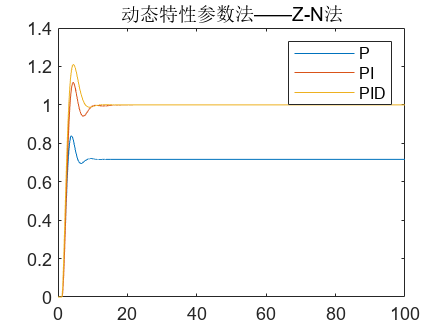

figure(7);
plot(ZN(:,1),ZN(:,2));hold on;
plot(ZN(:,1),ZN(:,3));hold on;
plot(ZN(:,1),ZN(:,4));hold on;
title("动态特性参数法——Z-N法");
legend('P','PI','PID');
hold off;